# Airplane Builder v.4: Compute aerodynamic performance of combined wing and tail vs. angle of attack

V.4 Adds import of leading and trailing edge shape of main wing from .csv files, to allow non-trapezoidal shapes

In this script, the calculations for the combined wing and tail are moved into a helper function buildAirplane(), so that the performance can be plotted vs. angle of attack.  Using this approach, we can check both the static and dynamic stability of the airplane.

## Set Design Parameters

### Define airplane parameters

Define parameters for the whole airplane, which are needed for the wing and tail inputs

% Reference values
airplaneParams.body = "airplane";
airplaneParams.airplaneAlpha = 0; % deg, Airplane current angle of attack, angle of airplane X axis relative to flight direction
airplaneParams.airDensity = 1; % kg/m^3, Set arbitrary values for air density and velocity so forces and moments can be calculated in real units
airplaneParams.Vinf = 27.4; % m/s
airplaneParams.g = 9.81; % m^2/s, acceleration due to gravity, without the minus sign
%  Reference area and length, to be replaced with values calculated from the main wing
airplaneParams.refLength = 1; % m, root chord length of main wing
airplaneParams.refArea = 14.29; % m, total main wing area
% Center of gravity for the airplane
airplaneParams.airplaneXcg = 0.3361; % m, Enter the calculated (X,Z) value for the airplane center of gravity, used to calculate the total pitching moment
airplaneParams.airplaneZcg = 0; % m


### Define main wing parameters

Define parameters used to build the wing with a trapezoidal shape and linearly varying angle of attack (twist) from root to tip.  Assume the wing section is hollow and is built from top and botton skin of specified thickness and density.  Note: other wing structures can be added to the mass and center of gravity calculations separately.

%Optional: read the leading edge and trailing edge coordinates from CSV files 
% tableLE = readtable("wingle.csv")
% Note trailing edge table starts at the tip instead of root
% tableTE = readtable("wingte.csv")
numSections = 100

numSections = 100

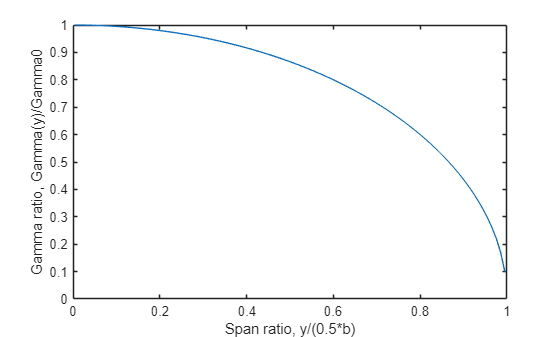


% Geometry and material parameters
wingParams.body = "main wing";
wingParams.section = "fx60126"; % name of airfoil section
wingParams.skinDensity = 100; % kg/m^3
wingParams.skinThickness = 0.005; % m
%  Location and section angle of attack for wing root
wingParams.XminRoot = 0; % m
wingParams.XmaxRoot = 0.7; % m
wingParams.YRoot = 0; % m
wingParams.ZRoot = 0; % m
wingParams.alphaRoot = 4.7; % deg
%  Location and section angle of attack for wing tip
wingParams.XminTip = 0; % m
wingParams.XmaxTip = 0.496; % m
wingParams.YTip = 11.95; % m
wingParams.ZTip = 0; % m
wingParams.alphaTip = 4.7; % deg
% Number of sections to use across the span
wingParams.numSections = numSections;

wingParams.Xcustom = false; % Set to false if not using a custom shape

% Compute and add the lift slope factor for the 3D wing
a3d = 5.96; % look up this value for your wing planview shape and aspect ratio
a2d = 2*pi; % use the value from thin airfoil theory
wingParams.liftSlopeRatio = a3d/a2d;
% Compute and add the spanwise distribution of circulation (lift), assuming
% an elliptical lift distribution (accurate only for an elliptical wing).
% You can replace this function with experimental data for any wing shape
spanRatio = linspace(0.5/wingParams.numSections,(wingParams.numSections-0.5)/wingParams.numSections,wingParams.numSections);
gammaRatio = sqrt(1-spanRatio.^2);
plot(spanRatio,gammaRatio);
xlabel("Span ratio, y/(0.5*b)");
ylabel("Gamma ratio, Gamma(y)/Gamma0");

wingParams.gammaRatio = gammaRatio;
% Add the Oswald efficiency factor for the 3D wing
wingParams.oswald = 0.95; % look up this value for your wing planview shape and aspect ratio
% Show the parameters
wingParams

wingParams = struct with fields:
              body: "main wing"
           section: "fx60126"
       skinDensity: 100
     skinThickness: 0.0050
          XminRoot: 0
          XmaxRoot: 0.7000
             YRoot: 0
             ZRoot: 0
         alphaRoot: 4.7000
           XminTip: 0
           XmaxTip: 0.4960
              YTip: 11.9500
              ZTip: 0
          alphaTip: 4.7000
       numSections: 100
           Xcustom: 0
    liftSlopeRatio: 0.9486
        gammaRatio: [1.0000 0.9999 0.9997 0.9994 0.9990 0.9985 0.9979 0.9972 0.9964 0.9955 0.9945 0.9934 0.9922 0.9908 0.9894 0.9879 0.9863 0.9846 0.9827 0.9808 0.9788 0.9766 0.9744 0.9720 0.9695 0.9669 0.9642 0.9614 0.9585 0.9555 … ] (1×100 double)
            oswald: 0.9500


% Set the airplane reference values using the main wing parameters
%  Compute the reference area and length, 
%   using length = root chord of the main wing, 
%   and area = main wing area (2x for both sides)
airplaneParams.refLength = wingParams.XmaxRoot - wingParams.XminRoot; % m
wingHalfArea = 0.5*(wingParams.YTip-wingParams.YRoot)*(wingParams.XmaxRoot-wingParams.XminRoot+wingParams.XmaxTip-wingParams.XminTip);
airplaneParams.refArea = 2*wingHalfArea; % m^2, assumes trapezoidal wing shape
% Note this area might be wrong for a custom wing shape, so enter the correct value after it is calculated:
% airplaneParams.refArea = 0.2; % m^2 <-- ENTER THIS VALUE

% Show the updated parameters
airplaneParams

airplaneParams = struct with fields:
             body: "airplane"
    airplaneAlpha: 0
       airDensity: 1
             Vinf: 27.4000
                g: 9.8100
        refLength: 0.7000
          refArea: 14.2922
      airplaneXcg: 0.3361
      airplaneZcg: 0


### Define horizontal tail parameters

Use the same parameters to define the horizontal tail

% Geometry and material parameters
tail_chord = 0.4 % m

tail_chord = 0.4000

tailParams.body = "tail wing";
tailParams.section = "fx60126"; % name of airfoil section
tailParams.skinDensity = 100; % kg/m^3
tailParams.skinThickness = 0.005; % m
%  Location and section angle of attack for wing root
tailParams.XminRoot = 10; % m
tailParams.XmaxRoot = 10+tail_chord; % m
tailParams.YRoot = 0; % m
tailParams.ZRoot = 2; % m
tailParams.alphaRoot = 4; % deg
%  Location and section angle of attack for wing tip
tailParams.XminTip = 10; % m
tailParams.XmaxTip = 10+tail_chord; % m
tailParams.YTip = 1; % m
tailParams.ZTip = 2; % m
tailParams.alphaTip = 4; % deg
% Number of sections to use across the span
tailParams.numSections = 100;

%  Specify a custom shape for the wing using Xmin, Xmax values
tailParams.Xcustom = false; % Set to false if not using a custom shape

% Compute and add the lift slope factor for the 3D wing
a3d = 5.0; % look up this value for your wing planview shape and aspect ratio
a2d = 2*pi; % use the value from thin airfoil theory
tailParams.liftSlopeRatio = a3d/a2d;
% Compute and add the spanwise distribution of circulation (lift), assuming
% an elliptical lift distribution (accurate only for an elliptical wing).
% You can replace this function with experimental data for any wing shape
spanRatio = linspace(0.5/tailParams.numSections,(tailParams.numSections-0.5)/tailParams.numSections,tailParams.numSections);
gammaRatio = sqrt(1-spanRatio.^2);
plot(spanRatio,gammaRatio);
xlabel("Span ratio, y/(0.5*b)");
ylabel("Gamma ratio, Gamma(y)/Gamma0");

tailParams.gammaRatio = gammaRatio;
% Add the Oswald efficiency factor for the 3D wing
tailParams.oswald = 0.85; % look up this value for your wing planview shape and aspect ratio
% Show the parameters
tailParams

tailParams = struct with fields:
              body: "tail wing"
           section: "fx60126"
       skinDensity: 100
     skinThickness: 0.0050
          XminRoot: 10
          XmaxRoot: 10.4000
             YRoot: 0
             ZRoot: 2
         alphaRoot: 4
           XminTip: 10
           XmaxTip: 10.4000
              YTip: 1
              ZTip: 2
          alphaTip: 4
       numSections: 100
           Xcustom: 0
    liftSlopeRatio: 0.7958
        gammaRatio: [1.0000 0.9999 0.9997 0.9994 0.9990 0.9985 0.9979 0.9972 0.9964 0.9955 0.9945 0.9934 0.9922 0.9908 0.9894 0.9879 0.9863 0.9846 0.9827 0.9808 0.9788 0.9766 0.9744 0.9720 0.9695 0.9669 0.9642 0.9614 0.9585 0.9555 … ] (1×100 double)
            oswald: 0.8500


## Calculate the baseline aerodynamic performance

### Build the wing tables and airplane results table

First calculate the airplane performance at zero angle of attack, and create plots showing the wing and tail 

[results,mainWingTable,tailWingTable] = buildAirplane(airplaneParams,wingParams,tailParams);
% Show the results
struct2table(results)

ans = 1×20 table
       body       airplaneAlpha      Fx        Fz      mainWingCD    tailWingCD    mainWingCL    tailWingCL    mainWingCM0    tailWingCM0    mainWingMy0    tailWingMy0      My0      massMoment     mass       Xcg        CL          CD         CM0        LoD  
    __________    _____________    ______    ______    __________    __________    __________    __________    ___________    ___________    ___________    ___________    _

% Show the results including area for the main wing.  I have run call buildWing to get this
% output here:
[~, results] = buildWing(wingParams,airplaneParams)

results = struct with fields:
           body: "main wing"
       wingArea: 14.2922
      rootChord: 0.7000
       wingSpan: 23.9000
    aspectRatio: 39.9666
             Fx: 439.1107
             Fz: 4.7933e+03
            My0: 503.1198
             CL: 0.8934
            CDi: 0.0067
            CDp: 0.0818
             CD: 0.0885
            CM0: 0.1340
           mass: 14.2922
     massMoment: 4.3148
            Xcg: 0.3019


disp("Calculated main wing area (including both sides) is " + results.wingArea + " m^2")

Calculated main wing area (including both sides) is 14.2922 m^2


### Plot the wing shapes

Create a plot showing both wing and tail on the right side of the airplane (from top view with nose toward the left), as well as the center of gravity

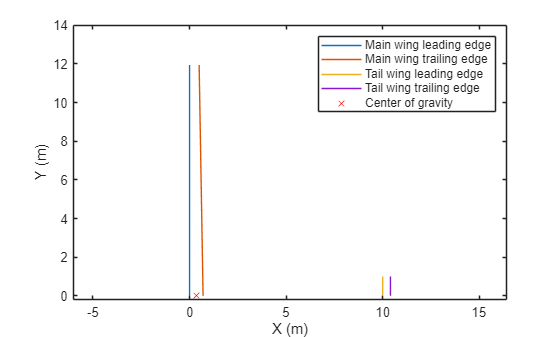

XleadingEdge = [mainWingTable.XminInner; mainWingTable.XminOuter(end)];
XtrailingEdge = [mainWingTable.XmaxInner; mainWingTable.XmaxOuter(end)];
Ysection = [mainWingTable.Yinner; mainWingTable.Youter(end)];
plot(XleadingEdge,Ysection);
hold on
plot(XtrailingEdge,Ysection);
hold on
XleadingEdge = [tailWingTable.XminInner; tailWingTable.XminOuter(end)];
XtrailingEdge = [tailWingTable.XmaxInner; tailWingTable.XmaxOuter(end)];
Ysection = [tailWingTable.Yinner; tailWingTable.Youter(end)];
plot(XleadingEdge,Ysection);
hold on
plot(XtrailingEdge,Ysection);
hold on
plot([airplaneParams.airplaneXcg],[0],"xr");
hold off
xlabel("X (m)");
ylabel("Y (m)");
legend(["Main wing leading edge","Main wing trailing edge","Tail wing leading edge","Tail wing trailing edge","Center of gravity"]);
ylim([-0.2 14]);
axis equal

### Plot the lift distributions

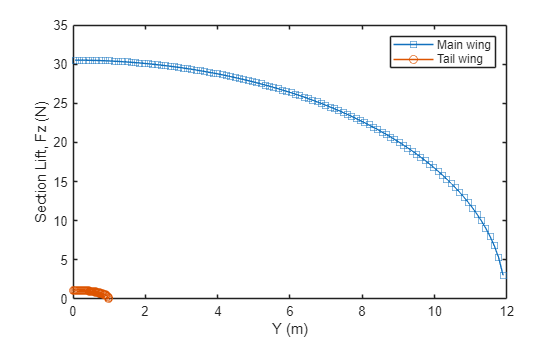

plot(mainWingTable.Ymid,mainWingTable.Fz,"-s")
hold on
plot(tailWingTable.Ymid,tailWingTable.Fz,"-o")
hold off
xlabel("Y (m)");
ylabel("Section Lift, Fz (N)");
legend(["Main wing","Tail wing"]);

## Calculate the aerodynamic performance vs. angle of attack

Next, we need to see how the airplane will perform over a range of angles of attack.  We can use the buildAirplane() function in a loop with angle of attack.

### Recalculate the performance at each angle

% Store the results from each angle in a table
resultsTable = table();
for alpha = -5:10
    % Calculate airplane properties at this angle of attack
    airplaneParams.airplaneAlpha = alpha;
    results = buildAirplane(airplaneParams,wingParams,tailParams); 
    % Add summary results to table
    resultsTable = [resultsTable ; struct2table(results)];
end
airplaneParams.airplaneAlpha = 0; % reset the angle of attack

% Show the results as a table
resultsTable

resultsTable = 16×20 table
       body       airplaneAlpha      Fx        Fz      mainWingCD    tailWingCD    mainWingCL    tailWingCL    mainWingCM0    tailWingCM0    mainWingMy0    tailWingMy0      My0      massMoment     mass       Xcg        CL          CD         CM0        LoD  
    __________    _____________    ______    ______    __________    __________    __________    __________    ___________    ___________    ___________    ___________   

### Plot the airplane aero coefficients vs. angle of attack

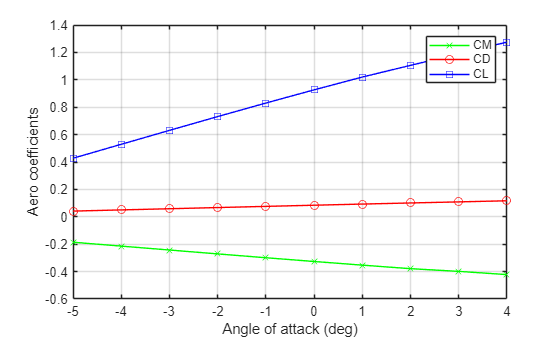

% Show the results as a plot vs. angle of attack
plot(resultsTable.airplaneAlpha,resultsTable.CM0,"-xg")
hold on
plot(resultsTable.airplaneAlpha,resultsTable.CD,"-or")
hold on
plot(resultsTable.airplaneAlpha,resultsTable.CL,"-sb")
grid on
hold off
legend("CM","CD","CL")
xlabel("Angle of attack (deg)");
ylabel("Aero coefficients");

Note how the combination of wing and tail is dynamically unstable.  This means that due to the positive slope of the pitching moment curve vs. alpha, when the angle of attack is increased the nose-up pitching moment increases, rotating the angle of attack higher.  This is due to the location of the center of gravity being too far aft of the wing center of pressure.  Even though the tail provides a balancing moment, yielding zero moment at a certain angle of attack (which is called static stability), it cannot produce enough lift at high angles to counteract the moment from the main wing.  This design is not dynamically stable and will not sustain level flight when there is a perturbation like a wind gust.  

## Make design changes to improve the dynamic stability

Now let's try shifting the center of gravity, which will be determined by the mass distribution of the entire airplane and cargo.

### Balance the moments at zero angle of attack, after shifting the center of gravity forward

After shifting the center of gravity, we will first need to change the tail parameters to achieve static stability.  Let's just reduce the angle of attack of the tail chord and tip

% Move the aircraft center of gravity for better balance
airplaneParams.airplaneXcg = 0.37; 
tailParams.alphaRoot % show the initial angle of attack of the tail

ans = 4


% Initial results
results = buildAirplane(airplaneParams,wingParams,tailParams)

results = struct with fields:
             body: "airplane"
    airplaneAlpha: 0
               Fx: 453.6709
               Fz: 4.9719e+03
       mainWingCD: 0.0885
       tailWingCD: 0.0750
       mainWingCL: 0.8934
       tailWingCL: 0.5946
      mainWingCM0: 0.1772
      tailWingCM0: -14.3367
      mainWingMy0: 665.6141
      tailWingMy0: -1.7221e+03
              My0: -1.0565e+03
       massMoment: 12.4748
             mass: 15.0922
              Xcg: 0.8266
               CL: 0.9267
               CD: 0.0846
              CM0: -0.2813
              LoD: 10.9593



disp("Balance around the center of gravity:");

Balance around the center of gravity:


disp("Main wing moment: " + results.mainWingMy0 + " N m");

Main wing moment: 665.6141 N m


disp("Tail wing moment: " + results.tailWingMy0 + " N m");

Tail wing moment: -1722.1421 N m


disp("Net moment about CG: " + results.My0 + " N m");

Net moment about CG: -1056.528 N m



% Lower the tail angle of attack to achieve static stability
tailParams.alphaRoot = -1.3;
tailParams.alphaTip = tailParams.alphaRoot;

% Updated results
results = buildAirplane(airplaneParams,wingParams,tailParams)

results = struct with fields:
             body: "airplane"
    airplaneAlpha: 0
               Fx: 439.4132
               Fz: 4.8615e+03
       mainWingCD: 0.0885
       tailWingCD: 0.0049
       mainWingCL: 0.8934
       tailWingCL: 0.2269
      mainWingCM0: 0.1772
      tailWingCM0: -5.6317
      mainWingMy0: 665.6141
      tailWingMy0: -676.4836
              My0: -10.8696
       massMoment: 12.4748
             mass: 15.0922
              Xcg: 0.8266
               CL: 0.9061
               CD: 0.0819
              CM0: -0.0029
              LoD: 11.0636



disp("Balance around the center of gravity:");

Balance around the center of gravity:


disp("Main wing moment: " + results.mainWingMy0 + " N m");

Main wing moment: 665.6141 N m


disp("Tail wing moment: " + results.tailWingMy0 + " N m");

Tail wing moment: -676.4836 N m


disp("Net moment about CG: " + results.My0 + " N m");

Net moment about CG: -10.8696 N m


### Recalculate the performance at each angle 

Next, recalculate the airplane results table vs. angle of attack with the updated tail angle

% Store the results from each angle in a table
resultsTable = table();
for alpha = -5:10
    % Calculate airplane properties at this angle of attack
    airplaneParams.airplaneAlpha = alpha;
    results = buildAirplane(airplaneParams,wingParams,tailParams);
    % Add summary results to table
    resultsTable = [resultsTable ; struct2table(results)];
end

% Show the results as a table
resultsTable

resultsTable = 16×20 table
       body       airplaneAlpha      Fx        Fz      mainWingCD    tailWingCD    mainWingCL    tailWingCL    mainWingCM0    tailWingCM0    mainWingMy0    tailWingMy0      My0      massMoment     mass       Xcg        CL          CD          CM0         LoD  
    __________    _____________    ______    ______    __________    __________    __________    __________    ___________    ___________    ___________    ___________ 

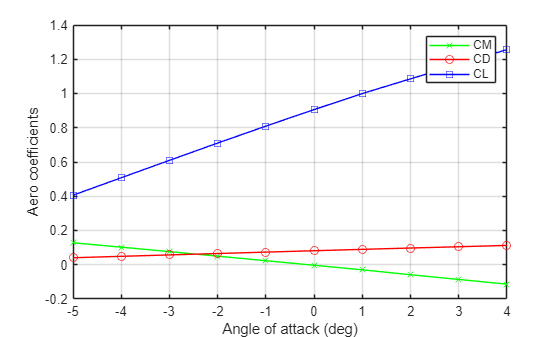


% Show the results as a plot vs. angle of attack
plot(resultsTable.airplaneAlpha,resultsTable.CM0,"-xg")
hold on
plot(resultsTable.airplaneAlpha,resultsTable.CD,"-or")
hold on
plot(resultsTable.airplaneAlpha,resultsTable.CL,"-sb")
grid on
hold off
legend("CM","CD","CL")
xlabel("Angle of attack (deg)");
ylabel("Aero coefficients");

Nice!  The airplane is now balanced statically with zero moment at zero angle of attack.  The airplane is now also dynamically stable with a negative slope of pitching moment vs. alpha.  If a disturbance increases the angle of attack, the negative moment will restore the angle by pitching the nose downward. 

As one final step, now that we have data for various angles of attack, let's create additional plots of the lift and drag of the wing and tail

### Create final plots to show the performance

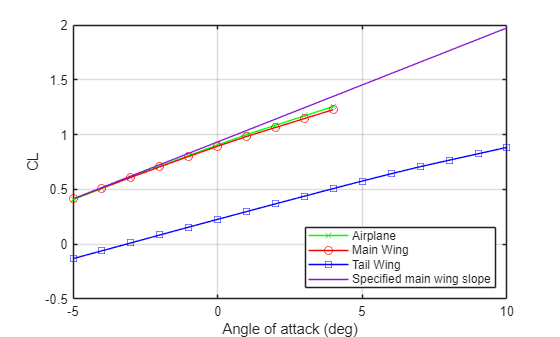

% Show CL vs. alpha for the airplane, main wing and tail
plot(resultsTable.airplaneAlpha,resultsTable.CL,"-xg")
hold on
plot(resultsTable.airplaneAlpha,resultsTable.mainWingCL,"-or")
hold on
plot(resultsTable.airplaneAlpha,resultsTable.tailWingCL,"-sb")
hold on
a = 2*pi*wingParams.liftSlopeRatio;
l = 5*pi/180*a;
plot([-5 10],[-l,2*l]+(resultsTable.mainWingCL(1)+l)); % Create a line with the specified main wing lift slope
grid on
hold off
legend(["Airplane","Main Wing","Tail Wing","Specified main wing slope"],Location="southeast");
xlabel("Angle of attack (deg)");
ylabel("CL");

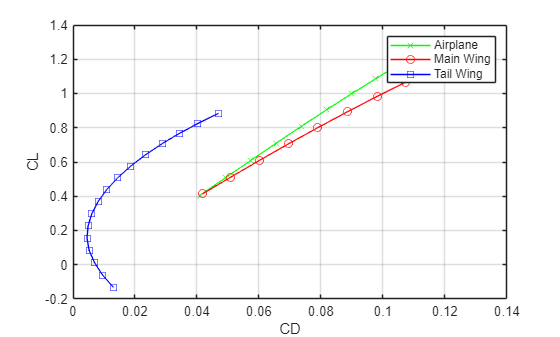


% Show CL vs. CD for the airplane, main wing and tail
plot(resultsTable.CD,resultsTable.CL,"-xg")
hold on
plot(resultsTable.mainWingCD,resultsTable.mainWingCL,"-or")
hold on
plot(resultsTable.tailWingCD,resultsTable.tailWingCL,"-sb")
hold off
grid on
legend("Airplane","Main Wing","Tail Wing")
xlabel("CD");
ylabel("CL");

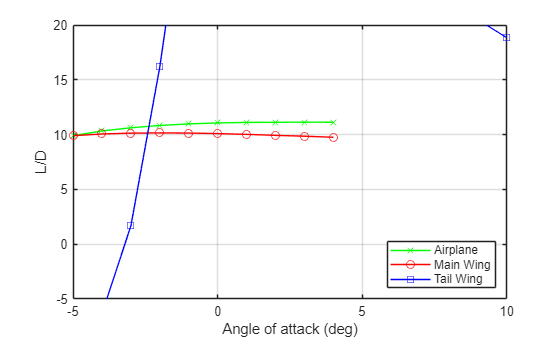


% Show L/D vs. alpha for the airplane, main wing and tail
plot(resultsTable.airplaneAlpha,resultsTable.LoD,"-xg")
hold on
plot(resultsTable.airplaneAlpha,resultsTable.mainWingCL./resultsTable.mainWingCD,"-or")
hold on
plot(resultsTable.airplaneAlpha,resultsTable.tailWingCL./resultsTable.tailWingCD,"-sb")
hold off
grid on
legend(["Airplane","Main Wing","Tail Wing"],Location="southeast");
xlabel("Angle of attack (deg)");
ylabel("L/D");
ylim([-5,20]);

## What's Next?

What's next?  Well, we didn't worry for now about the lift of the airplane matching the weight at cruise speed.  We need to determine the airframe weight, the cargo, and the flight speed to determine the needed lift at cruise.  Once the lift and center of gravity of the airplane are established, use a similar process as above to adjust the position of the wing and tail to get both static and dynamic stability. 

## Helper function to calculate aerodynamics of wing and tail

For a particular set of parameters, calculate the aerodynamic performance and return results in a struct.

function [results,mainWingTable,tailWingTable] = buildAirplane(airplaneParams,wingParams,tailParams)

Compute combined wing + tail properties

% Build the main wing
[mainWingTable, mainWingResults] = buildWing(wingParams,airplaneParams);

% Build the horizontal tail
[tailWingTable, tailWingResults] = buildWing(tailParams,airplaneParams);

% Create results struct
results.body = airplaneParams.body;
results.airplaneAlpha = airplaneParams.airplaneAlpha;   

% Sum the forces, moments and mass
results.Fx = mainWingResults.Fx + tailWingResults.Fx;
results.Fz = mainWingResults.Fz + tailWingResults.Fz;
results.mainWingCD = mainWingResults.CD;
results.tailWingCD = tailWingResults.CD;
results.mainWingCL = mainWingResults.CL;
results.tailWingCL = tailWingResults.CL;
results.mainWingCM0 = mainWingResults.CM0;
results.tailWingCM0 = tailWingResults.CM0;
results.mainWingMy0 = mainWingResults.My0;
results.tailWingMy0 = tailWingResults.My0;
results.My0 = mainWingResults.My0 + tailWingResults.My0;
results.massMoment = mainWingResults.massMoment + tailWingResults.massMoment; 
results.mass = mainWingResults.mass + tailWingResults.mass;
results.Xcg = results.massMoment/results.mass;

% Compute normalized values
q = 0.5*airplaneParams.airDensity*airplaneParams.Vinf^2;
refArea = airplaneParams.refArea;
refLength = airplaneParams.refLength;
results.CL = results.Fz/(q*refArea);
results.CD = results.Fx/(q*refArea);
results.CM0 = results.My0/(q*refArea*refLength);
results.LoD = results.CL/results.CD;

end

## Helper function to calculate wing geometry and aerodynamic properties

The function buildWing takes a struct with the needed input parameters.  It returns a table of properties for a spanwise series of sections, and a struct with results for the whole wing

function [wingTable, results] = buildWing(params,airplaneParams)


### Calculate wing geometry

Define the table for a wing or other body defined as a spanwise series of sections in even increments of Y.

tableVars = ["XminInner","XminOuter","XmaxInner","XmaxOuter","Xmid","Xcg","Yinner","Youter","Ymid","Zmid",...
    "alpha1","area","chord","mass","massMoment",...
    "alphae","Cl","Cd","Cmc4","Fa","Fn","Fx","Fz","My1","My0"];
numSections = params.numSections;
wingTable = array2table(zeros(numSections,numel(tableVars)),VariableNames=tableVars);

Populate the table with geometric parameters

for i=1:numSections
    if params.Xcustom 
        % Read custom shape from Xmin and Xmax arrays
        XminInner = params.Xmin(i);
        XminOuter = params.Xmin(i+1);
        XmaxInner = params.Xmax(i);
        XmaxOuter = params.Xmax(i+1);
    else
        % Create geometry of trapezoidal section in X,Y
        XminInner = params.XminRoot + (i-1)/numSections*(params.XminTip-params.XminRoot);
        XminOuter = params.XminRoot + i/numSections*(params.XminTip-params.XminRoot);    
        XmaxInner = params.XmaxRoot + (i-1)/numSections*(params.XmaxTip-params.XmaxRoot);
        XmaxOuter = params.XmaxRoot + i/numSections*(params.XmaxTip-params.XmaxRoot);    
    end
    Xmid = 0.25*(XminInner+XminOuter+XmaxInner+XmaxOuter);
    Yinner = params.YRoot + (i-1)/numSections*(params.YTip-params.YRoot);
    Youter = params.YRoot + i/numSections*(params.YTip-params.YRoot);    
    Ymid = 0.5*(Yinner+Youter);
    chord = 0.5*(XmaxInner-XminInner+XmaxOuter-XminOuter);
    area = (Youter-Yinner)*chord;
    % Set the midpoint of vertical position
    Zmid = params.ZRoot + (i-0.5)/numSections*(params.ZTip-params.ZRoot);
    % Set the angle of attack for this section relative to airplane X axis
    alpha1 = params.alphaRoot + (i-0.5)/numSections*(params.alphaTip-params.alphaRoot);
    % Assume hollow wing with upper and lower skin of constant thickness
    Xcg = Xmid;
    mass = 2*area*params.skinThickness*params.skinDensity;
    % Calculate the mass moment for this section about the origin to allow the center of gravity calculation for the airplane
    massMoment = Xcg*mass;
    % Add the geometric values to the table
    wingTable{i,1:15} = [XminInner,XminOuter,XmaxInner,XmaxOuter,Xmid,Xcg,Yinner,Youter,Ymid,Zmid,alpha1,area,chord,mass,massMoment];
end


### Calculate wing aerodynamics

#### Load airfoil data

Retrieve aerodynamic coefficient data for the specified airfoil by matching filename, assuming the first row contains the variable names.

Required variables: "Alpha", "Cl", "Cd", "Cm"

filename = "airfoils/data-" + params.section + ".csv";
coefTable = readtable(filename);

#### Calculate wing aerodynamics per spanwise section

Populate the table with aerodynamic values for each section.

q = 0.5*airplaneParams.airDensity*airplaneParams.Vinf^2;
for i=1:numSections
    % Angle of attack of this section, relative to body X axis
    alpha1 = wingTable{i,"alpha1"};
    % Angle of attack of this section relative on flight direction
    alpha = alpha1 + airplaneParams.airplaneAlpha;
    % Effective angle of attack of this section, determined based on 3D
    % wing theory, relative to flight direction
    %  First, look up the 2D lift coefficient
    Cl2d = interp1(coefTable.Alpha,coefTable.Cl,alpha);    
    %  Compute the chord ratio
    rootChord = params.XmaxRoot - params.XminRoot;
    chordRatio = wingTable{i,"chord"}/rootChord;
    %  Compute the 3D lift coefficient by scaling
    Cl3d = Cl2d * params.liftSlopeRatio*params.gammaRatio(i)/chordRatio;
    %  Look up the effective angle of attack for this Cl value
    alphae = interp1(coefTable.Cl,coefTable.Alpha,Cl3d);
    % Look up coefficient values from table
    Cl = interp1(coefTable.Alpha,coefTable.Cl,alphae);
    Cd = interp1(coefTable.Alpha,coefTable.Cd,alphae);
    Cmc4 = interp1(coefTable.Alpha,coefTable.Cm,alphae);
    % Compute the axial and normal forces, and rotate to Fx, Fz (body X,Z axes)
    area = wingTable{i,"area"};
    Fa = Cd*q*area;    
    Fn = Cl*q*area;
    Fx = Fa*cos(alpha1*pi/180.) + Fn*sin(alpha1*pi/180.);
    Fz = -Fa*sin(alpha1*pi/180.) + Fn*cos(alpha1*pi/180.);
    % Compute moment about the quarter chord
    chord = wingTable{i,"chord"};
    My1 = Cmc4*q*area*chord;
    % Compute moment contribution about the airplane center of gravity,
    % by applying the aerodynamic forces at the quarter chord and adding
    % the aerodynamic pitching moment
    Xmid = wingTable{i,"Xmid"};
    Zmid = wingTable{i,"Zmid"};
    XmomentArm = Xmid - 0.25*chord - airplaneParams.airplaneXcg;
    ZmomentArm = Zmid - airplaneParams.airplaneZcg;
    My0 = My1 - Fz*XmomentArm + Fx*ZmomentArm;
    % Add the aerodynamic values to the table
    wingTable{i,16:end} = [alphae,Cl,Cd,Cmc4,Fa,Fn,Fx,Fz,My1,My0];
end

### Calculate overall wing properties

Calculate contribution of the wing to airplane lift, drag and moment, as well as mass and center of gravity.  Note all calculations are relative to the body X,Z axes.  Aspect ratio is defined for the full wing, AR = b^2/S, where b is span of the full wing, S is area of the full wing.

% Create a struct with results
%  Name this body
results.body = params.body;
%  Calculate the wing area (for the main wing can use this to confirm the
%   reference area value)
results.wingArea = 2*sum(wingTable.area); % Area of whole wing, for main wing this is also the reference area
results.rootChord = params.XmaxRoot - params.XminRoot;
results.wingSpan = 2*(params.YTip - params.YRoot); % Span for whole wing
results.aspectRatio = results.wingSpan^2/results.wingArea; % AR = b^2/S for whole wing
%  Calculate 3D aerodynamic coefficients in the body coordinate system
results.Fx = 2*sum(wingTable.Fx);
results.Fz = 2*sum(wingTable.Fz);
results.My0 = 2*sum(wingTable.My0);
results.CL = results.Fz/(q*results.wingArea);
results.CDi = results.CL^2/(pi*results.aspectRatio*params.oswald); % induced drag from 3D wing theory
results.CDp = results.Fx/(q*results.wingArea); % profile drag, meaning drag from 2D airfoil characteristics only
results.CD = results.CDi + results.CDp;
results.CM0 = results.My0/(q*results.wingArea*results.rootChord);
%  Calculate the mass and mass moment for the center of gravity calculation
results.mass = 2*sum(wingTable.mass);
results.massMoment = 2*sum(wingTable.massMoment);
%  Center of gravity for the isolated wing
results.Xcg = results.massMoment/results.mass;

end
